% clear
% clc
% load("tempAll.mat");
% inputs={};
% outputs={};
% nt=60;
% for i=1:18
%     input=zeros(31,6000/nt);
%     output=zeros(1,6000/nt);
%     for t=nt:nt:6000
%         tmpIn=[node_temp{i}(t-nt+1:t,:),node_speed{i}(t-nt+1:t)];
%         tmpOut=node_error{i}(t-nt+1:t);
%         input(:,t/nt)=mean(tmpIn)';
%         output(:,t/nt)=mean(tmpOut)';
%     end
%     output=output-output(1);
%     inputs{i}=input;
%     outputs{i}=output;
% end

clear;
load LSTM_TF_data.mat;
groupTest=[5,11,17];
groupTrain=[1:4,6:10,12:16,18];
for i=1:size(groupTrain,2)
    XTrain{i,1}=inputs{groupTrain(i)};
    YTrain{i,1}=outputs{groupTrain(i)};
end

numResponses = 1;
numFeatures = 29;
numHiddenUnits = 200;
H0 = zeros(numHiddenUnits,1);
C0 = zeros(numHiddenUnits,1);
mu = mean([XTrain{:}],2);
sig = std([XTrain{:}],0,2);

for i = 1:numel(XTrain)
    XTrain{i} = (XTrain{i} - mu) ./ sig;
end
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.5)
    fullyConnectedLayer(numResponses)
    regressionLayer];
maxEpochs = 10000;
miniBatchSize = 100;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0,...
    'ExecutionEnvironment','auto');

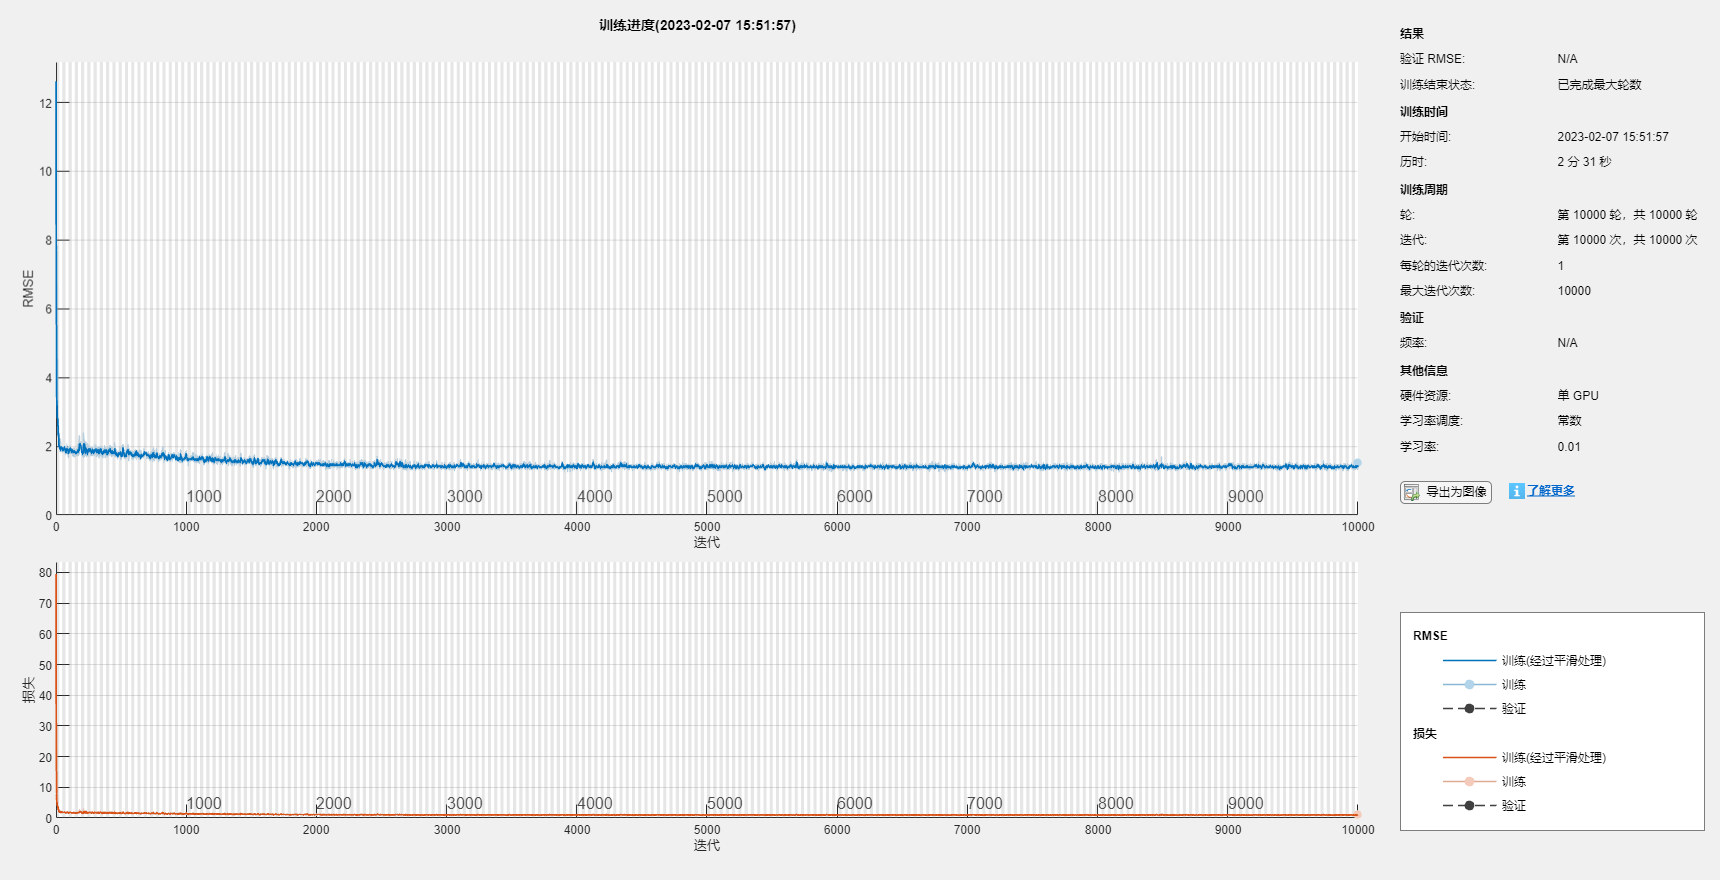

%net = trainNetwork(XTrain,YTrain,layers,options);
load('net.mat');

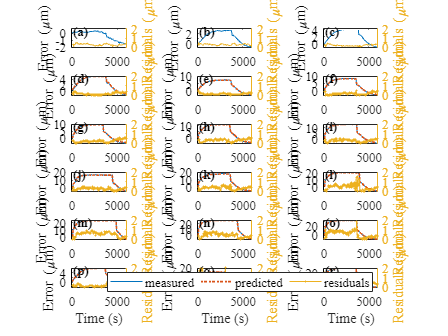

%训练输出
YTrain_Pred = predict(net,XTrain,'MiniBatchSize',1);

rmses=zeros(numel(XTrain),1);
for i = 1:numel(XTrain)
    rmses(i) = sqrt(mean(mean((YTrain_Pred{i}-YTrain{i}).^2)));
end
t=60:60:6000;
figure
for i = 1:numel(YTrain_Pred)
    subplot(6,3,i)
    
    plot(t,YTrain{i})
    hold on
    plot(t,YTrain_Pred{i},':',"LineWidth",1.5)
    ylabel("Error (\mum)");
    yyaxis right;
    plot(t,abs(YTrain_Pred{i}-YTrain{i}),'.-')
    hold off
    
    ylim([0 2]);
    text(100,1.8,"("+ char(96+i)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    ylabel("Residuals (\mum)");
    %xlabel("Time (s)");

    set(gca,'fontsize',12,'fontname','times new roman');
end
% legend({'measured','predicted','residuals'},'NumColumns',3);
% set(gca,'fontsize',12,'fontname','times new roman');

%测试输出
for i=1:size(groupTest,2)
    XTest{i,1}=inputs{groupTest(i)};
    YTest{i,1}=outputs{groupTest(i)};
end
for i = 1:numel(XTest)
    XTest{i} = (XTest{i} - mu) ./ sig;
end
YTest_Pred = predict(net,XTest,'MiniBatchSize',1);
rmses=zeros(numel(XTest),1);
for i = 1:numel(YTest)
    rmses(i) = sqrt(mean(mean((YTest_Pred{i}-YTest{i}).^2)));
end
t=60:60:6000;

for i = 1:numel(YTest_Pred)
    subplot(6,3,i+15)
    
    plot(t,YTest{i})
    hold on
    plot(t,YTest_Pred{i},':',"LineWidth",1.5)
    ylabel("Error (\mum)");
    yyaxis right;
    plot(t,abs(YTest_Pred{i}-YTest{i}),'.-')
    hold off
    
    ylim([0 2]);
    text(100,1.8,"("+ char(96+i+15)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    xlabel("Time (s)");
    ylabel("Residuals (\mum)");
    set(gca,'fontsize',12,'fontname','times new roman');
end
legend({'measured','predicted','residuals'},'NumColumns',3,'fontsize',12,'fontname','times new roman');